# Class I Drag Polar Sanity Checks

clear; close; clc;

## Define Parameters

% wing parameters
t2c_wing_root = .18;
%t2C_wing_midSpan = .18;
t2c_wing_tip = .12;

% empenage parameters
% Horizontal Tail
x_ac_h = convlength(199.8,"in","m"); % distance from LE of wing MGC to AC of horizontal-tail (m)
t2c_h_root = .12;
t2c_h_tip = .12;
% Verticle Tail
x_ac_v = convlength(189.7,"in","m"); % distance from LE of wing MGC to AC of verticle-tail (m)
t2c_v_root = .14;
t2c_v_tip = .12;
% fuselage parameters
dist_nose2LE = 3.0226; % distance from nose of fuselage to LE of wing root

% nasell parameters

% drag estimation parameters
c_f = .00245; % Equivalent skin friction coefficient (~)
A = 29; % Aspect Ratio (~)
e = .9; % Oswald Efficiency Factor (~)
C_L_max = 2.5; % maximum lift coefficient (~)

% this flapped drag isn't right for a C_L of 2.5 it too low for C_L of 1.5 it's ok
Delta_C_D_0_flaps_L = .008; % zerolift drag increment due to landing flaps
Delta_C_D_0_gear = .02; % zerolift drag increment due to landing gear TODO: estimate better!

% ploting parameters for drag Polar
nPlotPoints = 100; % number of points to plot for drag polar

% atmospheric parameters for speed polar
T_nonstand = 10; % Temperature offset deg C of non standard day
alt_des = convlength(3000,"ft","m"); % Desired altitude m
[rho,~] = Nonstandardrho(alt_des, T_nonstand);
W = 700*9.81

W = 6867


% airbrake parameters
S_AB2S = 1.5/7.5; % impacted planform area of airbrake as fraction of planform area
h_AB= .18;

## Find S_wet of Planar Surfaces

## Wing

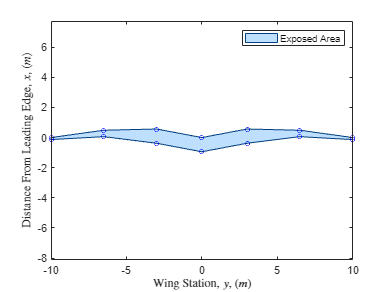



% Load coordinates of wing
load('Arychtas_Wing_Coordinates_Class_I_V_0.mat');
wing_x_coords = wingCoordinates(1,:);
wing_y_coords = wingCoordinates(2,:);

c_r_wing = wing_y_coords(end);
c_t_wing = wing_y_coords(length(wing_y_coords)/2+1);

% plot the wing to ensure it has been produced properly
figure;
p = fill([wing_x_coords, -fliplr(wing_x_coords)], [wing_y_coords,fliplr(wing_y_coords)], [.5,.75,1], "FaceAlpha",.5, "EdgeColor",[.0,.25,.5], "Marker","o"); hold on
p.MarkerEdgeColor = "blue"; p.MarkerSize = 4;
%plot([wing_x_coords, -fliplr(wing_x_coords)], [wing_y_coords,fliplr(wing_y_coords)])
%title("Full Span Wing");
xlabel("Wing Station, $y$, $\left(m\right)$", "Interpreter","latex"); ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", "Interpreter","latex");
axis equal;
legend(["Exposed Area"]);


% planform area of wing
S = 2 * trapz(wing_x_coords,wing_y_coords); % compute the exposed planform area of wing (m) NOTE: twice planform semispan

% i am doing this wrong i need to remove the fuselage
S_exposed_wing = 2 * trapz(wing_x_coords,wing_y_coords); % compute the exposed planform area of wing (m) NOTE: twice exposed semispan

S_wet_wing = WettedArea_Planform_Class_I(S_exposed_wing, t2c_wing_root, t2c_wing_tip, c_r_wing, c_t_wing)

S_wet_wing = 25.2228


% TODO: fix bad accounting
S_wet_wing_CAD = 19.8; % wetted area from cad model (m^2)


## Empenage

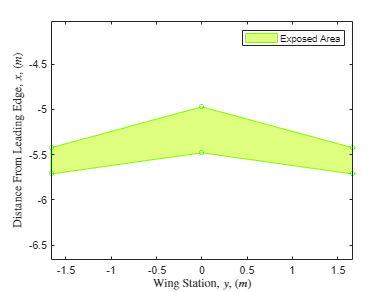

% horizontal tail
load("Arychtas_hTail_Coordinates_Class_I_V_0.mat")
c_bar_h = hTailMeanGeometricCord(1); % mean geometric cord
x_mgc_h = hTailMeanGeometricCord(2); y_mgc_h = hTailMeanGeometricCord(2); % relative location of mgc
x_h_LE = x_ac_h - c_bar_h/4;

x_coords_hTail = hTailCoordinates(1,:);
y_coords_hTail = hTailCoordinates(2,:) - x_h_LE;

c_r_h = y_coords_hTail(1) - y_coords_hTail(4);
c_t_h = y_coords_hTail(2) - y_coords_hTail(3);

% produce plot
figure;
p = fill([x_coords_hTail, -fliplr(x_coords_hTail)], [y_coords_hTail,fliplr(y_coords_hTail)], [.75,1,0], "FaceAlpha",.5, "EdgeColor",[.5,1,0], "Marker","o"); hold on;
p.MarkerEdgeColor = "green"; p.MarkerSize = 4;
xlabel("Wing Station, $y$, $\left(m\right)$", "Interpreter","latex"); ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", "Interpreter","latex");
axis equal;
legend(["Exposed Area"]);


% i am doing this wrong i need to remove the fuselage
S_exposed_hTail = 2*trapz(x_coords_hTail,y_coords_hTail); % compute the exposed planform area of wing (m) NOTE: twice exposed semispan

% wetted area of horizontal tail
S_wet_hTail = WettedArea_Planform_Class_I(S_exposed_hTail, t2c_h_root, t2c_h_tip, c_r_h, c_t_h)

S_wet_hTail = 2.7367

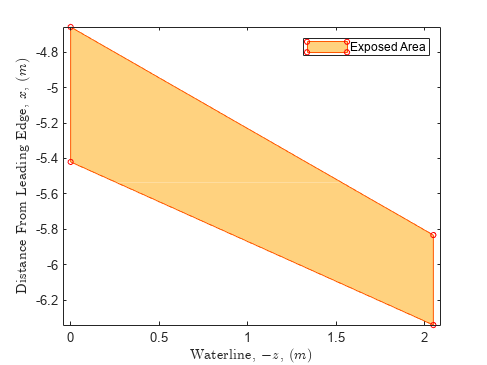



% Verticle Tail
load("Arychtas_vTail_Coordinates_Class_I_V_0.mat")
c_bar_v = vTailMeanGeometricCord(1); % mean geometric cord
x_mgc_v = vTailMeanGeometricCord(2); y_mgc_v = vTailMeanGeometricCord(2); % relative location of mgc
x_v_LE = x_ac_v - c_bar_v/4;

z_coords_vTail = vTailCoordinates(2,:) - x_v_LE; % get the z coords - positiion relative to LE
y_coords_vTail = vTailCoordinates(1,:); % get the y coords - TODO:position ouside the fuselage


c_r_v = z_coords_vTail(1) - z_coords_vTail(4);
c_t_v = z_coords_vTail(2) - z_coords_vTail(3);

% produce plot
figure;
p = fill(y_coords_vTail, z_coords_vTail, [1,.65,0], "FaceAlpha",.5, "EdgeColor",[1,.35,0], "Marker","o"); hold on;
p.MarkerEdgeColor = "red"; p.MarkerSize = 4;
xlabel("Waterline, $-z$, $\left(m\right)$", "Interpreter","latex"); ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", "Interpreter","latex");
axis equal;
legend(["Exposed Area"]);


% i am doing this wrong i need to remove the fuselage
S_exposed_vTail = abs(2*trapz(z_coords_vTail,y_coords_vTail)); % compute the exposed planform area of wing (m) NOTE: twice exposed semispan

% wetted area of horizontal tail
S_wet_vTail = WettedArea_Planform_Class_I(S_exposed_vTail, t2c_v_root, t2c_v_tip, c_r_v, c_t_v)

S_wet_vTail = 5.4280


% TODO: fix bad accounting
S_wet_empenage_CAD = 6.11; % wetted area from cad model (m^2)


## Find S_wet of Fuselage

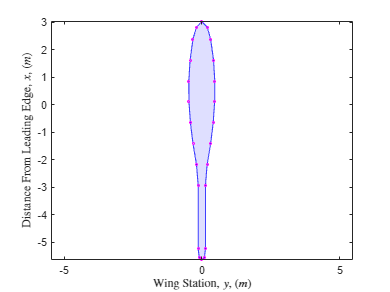

% Import The Preimeter of the section into matlab

% set up import options for importing the section data
opts = delimitedTextImportOptions("NumVariables", 3);
opts.DataLines = [2, Inf]; opts.Delimiter = ","; % Specify range and delimiter
opts.VariableNames = ["Var1", "distanceFromNosein", "perimeterin"]; opts.SelectedVariableNames = ["distanceFromNosein", "perimeterin"]; opts.VariableTypes = ["string", "double", "double"]; % Specify column names and types
opts.ExtraColumnsRule = "ignore"; opts.EmptyLineRule = "read"; % Specify file level properties
opts = setvaropts(opts, "Var1", "WhitespaceRule", "preserve"); opts = setvaropts(opts, "Var1", "EmptyFieldRule", "auto"); % Specify variable properties
tbl = readtable("Arychtas_Cross_section_locations_Class_I_V_0.csv", opts); % Import the data

% convert the output type
distanceFromNose = tbl.distanceFromNosein;
perimeter = tbl.perimeterin;

% convert units to SI
distanceFromNose = convlength(distanceFromNose,"in","m");
perimeter = convlength(perimeter,"in","m");

clear opts tbl; % clear temportary variables

% plot the fuselage to confim accuracy
figure;
fill([perimeter/(2*pi), -perimeter/(2*pi)], -[distanceFromNose, distanceFromNose] + dist_nose2LE, [.75,.75,1],"FaceAlpha",.5,"EdgeColor","none"); 
hold on
p = plot([perimeter/(2*pi), -perimeter/(2*pi)], -distanceFromNose + dist_nose2LE, "-o", "Color",[.25,.25,1], "LineWidth",1, "MarkerSize",2, "MarkerEdgeColor","magenta"); axis equal;
% p.MarkerEdgeColor = "magenta"; p.MarkerSize = 4; p.Marker = "o"
xlabel("Wing Station, $y$, $\left(m\right)$", Interpreter="latex");
ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", Interpreter="latex");
axis equal; legend off

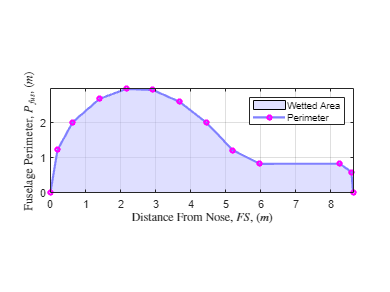


% produce the fuselage perimeter plot
figure;
area(distanceFromNose,perimeter,"FaceColor",[.75,.75,1],"FaceAlpha",.5); hold on
p = plot(distanceFromNose,perimeter,"-o","LineWidth",2, "Color",[.5,.5,1]); axis equal;
p.MarkerEdgeColor = "magenta"; p.MarkerSize = 4;
xlabel("Distance From Nose, $FS$, $\left(m\right)$", Interpreter="latex");
ylabel("Fuselage Perimeter, $P_{fus}$, $\left(m\right)$", Interpreter="latex");
%title("Perimeter Plot", Interpreter="latex")
grid on; ylim([0,inf]); xlim([0,max(distanceFromNose)])
legend(["Wetted Area","Perimeter"])

%hold on;

%integrate the fuselage perimeter to get the wetted area
S_wet_fuse_perimeterMethod = trapz(distanceFromNose,perimeter) % compute the wetted area Via inetgrating the perimeter

S_wet_fuse_perimeterMethod = 14.9911


% compute the wetted area from the  approximate calculation method
l_n = distanceFromNose(perimeter == max(perimeter)) - distanceFromNose(1); % length of nose (m)
l_f = distanceFromNose(end) - distanceFromNose(1); % length of fuselage (m)
d_f = max(perimeter)/pi; % hydraulic diameter of the maximum thickness section (m)
S_wet_fuse_diamMethod = WettedArea_Fuselage_Class_I(d_f, l_f, false, l_n)

S_wet_fuse_diamMethod = 23.3075


PercentError = (S_wet_fuse_diamMethod - S_wet_fuse_perimeterMethod) * 2 / (S_wet_fuse_diamMethod + S_wet_fuse_perimeterMethod) * 100

PercentError = 43.4290


% TODO: fix bad accounting
S_wet_fuse_CAD = 15.3; % wetted area from cad model (m^2)

## Find S_wet of Nacells

% l_spinner = 
% l_pylon = 

% TODO: fix bad accounting
S_wet_nacells_CAD = 1.38; % wetted area from cad model (m^2)

## Total wetted area

S_wet_est = S_wet_fuse_perimeterMethod + S_wet_wing + S_wet_hTail + S_wet_vTail

S_wet_est = 48.3787


S_wet_CAD = S_wet_fuse_CAD + S_wet_wing_CAD + S_wet_empenage_CAD + S_wet_nacells_CAD

S_wet_CAD = 42.5900


PercentError_total = (S_wet_est - S_wet_CAD) * 2 / (S_wet_est + S_wet_CAD) * 100

PercentError_total = 12.7267


S_wet = S_wet_CAD

S_wet = 42.5900

## Drag estimation

% compute zero lift drag coefficient 
f = EquivalentParasiteArea(c_f, S_wet) % equivalent parasite area

f = 0.1038

C_D_0 = DragCoefficientZeroLift(f,S) % zero lift drag coefficient

C_D_0 = 0.0084


%TODO: clean this up
C_D_AB = DragCoefficient_Airbrakes(S_AB2S)

C_D_AB = 0.0600

%C_D_AB = .2*.3
% Note: we should ultimatley end up with flap settings: Landing, Thermalling, Zero, Negative One, Negative Two
C_D_0 = C_D_0 + [0; Delta_C_D_0_gear; Delta_C_D_0_flaps_L; Delta_C_D_0_flaps_L + Delta_C_D_0_gear; C_D_AB; .6 * C_D_AB; .3 * C_D_AB; Delta_C_D_0_gear + C_D_AB; Delta_C_D_0_gear + C_D_AB + Delta_C_D_0_flaps_L]

C_D_0 =     0.0084
    0.0284
    0.0164
    0.0364
    0.0684
    0.0444
    0.0264
    0.0884
    0.0964


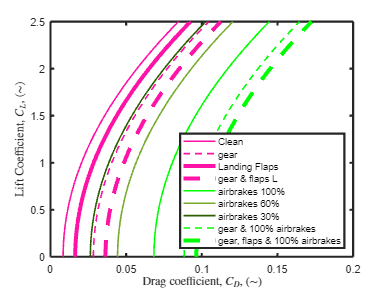


% compute drag polar
C_L = linspace(0, C_L_max, nPlotPoints); % lift coefficients to plot

% TODO: must incorporate changine oswald efficiency

C_D = zeros(size(C_D_0,1),nPlotPoints); % initialize C_D
for i = 1:size(C_D,1)
    C_D(i,:) = DragPolar_parabolic(C_D_0(i), C_L, A, e); % clean drag polar
end

% plot Drag Polar
figure
dp = plot(C_D, C_L); 
configurationNames = ["Clean", "gear", "Landing Flaps", "gear & flaps L", "airbrakes 100%", "airbrakes 60%", "airbrakes 30%", "gear & 100% airbrakes", "gear, flaps & 100% airbrakes"];
legend(configurationNames, "Location","southeast");
xlabel("Drag coefficient, $C_D$, $\left(\sim\right)$", Interpreter="latex");
ylabel("Lift Coefficient, $C_{L}$, $\left(\sim\right)$", Interpreter="latex");

% produce colour order for plot
b1 = [0.00,0.45,0.74]; % blue
p1 = [1.00,0.07,0.65]; % pink
g1 = [0.37,0.57,0.09]; % gark green
o1 = [1.00,0.41,0.16]; % orange
g2 = [0.47,0.67,0.19]; % lighter green
g3 = [0.00,1.00,0.00]; % lime green
g0 = [0.17,0.37,0.00];
%polarColours = [b1; b1; p1; p1; g3; g2; g1; g3; g3];
polarColours = [p1; p1; p1; p1; g3; g2; g0; g3; g3];
%polarColours = [b1; b1; b1; b1; g3; g2; g0; g3; g3];

colororder(polarColours);

lineStyles = ["-", "--", "-", "--", "-", "-", "-", "--", "--"];
linewidths = [1,1,2.5,2.5,1,1,1,1,2.5]*1.5;

for i = 1:length(lineStyles)
    set(dp(i), "LineStyle", lineStyles(i));
    set(dp(i), "LineWidth", linewidths(i));
end

set(gca,"LineWidth", 2);



% speed polar
figure; 
%% TODO: Limit graphs with stall

W2S = W/S % compute wing loading

W2S = 552.9566

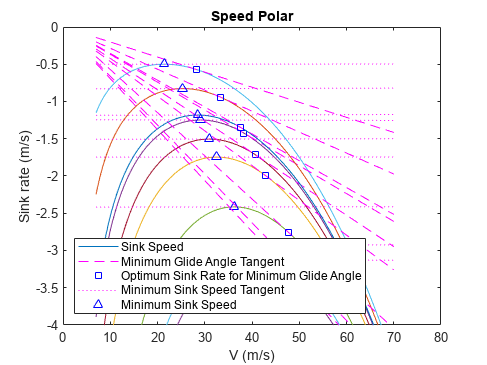

Vmin = 7;
Vmax = 70;
%clean
[V, V_sink, V_sinktan1, pt1, ~, ~, ~, ~, ~, V_sinktan2, pt2, ~, ~, ~, ~, ~] = V_sink(rho, A, e(1), C_D_0(1), W2S, Vmin, Vmax);
speedpolarplot(V,V_sink, V_sinktan1, pt1, V_sinktan2, pt2);
hold on
%flaps

for i = 1:length(C_D_0)
    clear V V_sink V_sinktan1 pt1 V_sinktan2 pt2
    [V, V_sink, V_sinktan1, pt1, ~, ~, ~, ~, ~, V_sinktan2, pt2, ~, ~, ~, ~, ~] = V_sink(rho, A, e(1), C_D_0(i), W2S, Vmin, Vmax);
    speedpolarplot(V,V_sink, V_sinktan1, pt1, V_sinktan2, pt2);
    hold on;
end

hold on

## Airbrakes

%Check in the dirtiest configuration the L/D >= 7:1
clear V V_sink V_sinktan1 pt1 V_sinktan2 pt2
% currently assuing last onfig is diriest (TODO: revisit that assumption)
[~, ~, ~, ~, gamma_opt, L_D_optgam, V_optgam, ~, ~, ~, ~, ~, ~, ~, ~, ~] = V_sink(rho, A, e(1), max(C_D_0), W2S, Vmin, Vmax);

if L_D_optgam < 7 % check compliance with cs-22
    fprintf("L/D in dirtiest config %.3g < 7", L_D_optgam);
end

%%%%%
% compute dive speed
%%%%%

% cs-22 45 degree dive


% verticle dive


% check that speed in a 45 deg dive is sufficiently limited
C_D_0(5); % drag coeff with airbrakes
gamma_cs22 = deg2rad(45);
V_D_cs22 = SpeedDive(W2S, C_D_0(5), A, e, rho, gamma_cs22);
V_D_ = SpeedDive(W2S, C_D_0(1), A, e, rho, gamma_cs22)

V_D_ = 274.8213

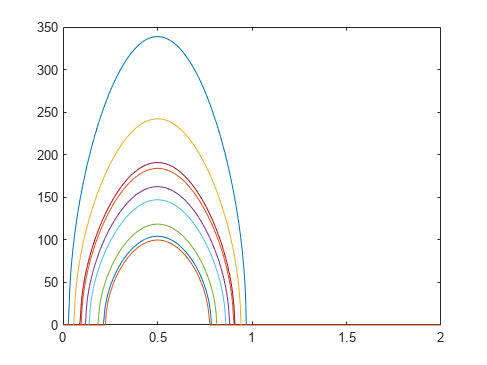



% compute dive speeds
gams = linspace(0,2*pi,500);
V_D = real(SpeedDive(W2S, C_D_0, A, e, rho, gams));

% plot dive speed vs angle and flight congfiguration.
figure;
plot(gams/pi,V_D)

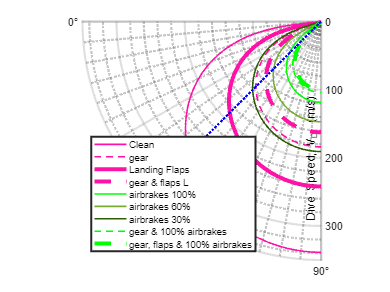

dp = polarplot(gams, V_D, "LineWidth", 2);
hold on;
polarplot([pi/4,pi/4], [0,max(real(V_D), [], "all")], ":b", "LineWidth", 2);

pax = gca;
pax.ThetaDir = "counterclockwise"; pax.ThetaZeroLocation = "left";
pax.ThetaLim = [0,90];
pax.RAxisLocation = 90; pax.RGrid = "on";

% colour to match drag polar
colororder(polarColours);
for i = 1:length(lineStyles)
    set(dp(i), "LineStyle", lineStyles(i));
    set(dp(i), "LineWidth", linewidths(i));
end
set(gca,"LineWidth", 2);
grid minor;
legend(configurationNames)%, "Location","southeast");
legend(configurationNames, "Location","southwest");
subtitle("Dive Speed, V_D, (m/s)","Position",[90,200], "Rotation",90)

## Produce 3 View Plots

## Top view

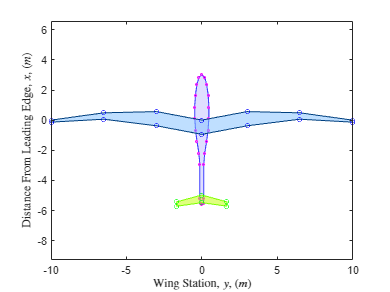

figure;
% fuselage
fill([perimeter/(2*pi), -perimeter/(2*pi)], -[distanceFromNose, distanceFromNose] + dist_nose2LE, [.75,.75,1],"FaceAlpha",.5,"EdgeColor","none"); 
hold on;
p = plot([perimeter/(2*pi), -perimeter/(2*pi)], -distanceFromNose + dist_nose2LE, "-o", "Color",[.25,.25,1], "LineWidth",1, "MarkerSize",2, "MarkerEdgeColor","magenta"); axis equal;

% wing 
p = fill([wing_x_coords, -fliplr(wing_x_coords)], [wing_y_coords,fliplr(wing_y_coords)], [.5,.75,1], "FaceAlpha",.5, "EdgeColor",[.0,.25,.5], "Marker","o"); hold on
p.MarkerEdgeColor = "blue"; p.MarkerSize = 4;

% horizontal stabilizer
p = fill([x_coords_hTail, -fliplr(x_coords_hTail)], [y_coords_hTail,fliplr(y_coords_hTail)], [.75,1,0], "FaceAlpha",.5, "EdgeColor",[.5,1,0], "Marker","o"); hold on;
p.MarkerEdgeColor = "green"; p.MarkerSize = 4;

% figure Labels
xlabel("Wing Station, $y$, $\left(m\right)$", Interpreter="latex");
ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", Interpreter="latex");
axis equal; legend off

## Side view

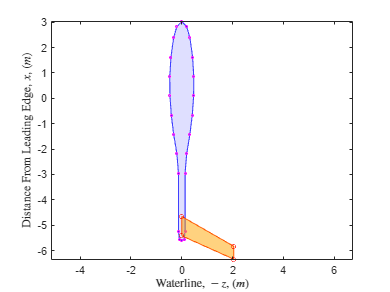

figure;
% fuselage
fill([perimeter/(2*pi), -perimeter/(2*pi)], -[distanceFromNose, distanceFromNose] + dist_nose2LE, [.75,.75,1],"FaceAlpha",.5,"EdgeColor","none"); 
hold on;
p = plot([perimeter/(2*pi), -perimeter/(2*pi)], -distanceFromNose + dist_nose2LE, "-o", "Color",[.25,.25,1], "LineWidth",1, "MarkerSize",2, "MarkerEdgeColor","magenta"); axis equal;

% verticle stabilizer
p = fill(y_coords_vTail, z_coords_vTail, [1,.65,0], "FaceAlpha",.5, "EdgeColor",[1,.35,0], "Marker","o"); hold on;
p.MarkerEdgeColor = "red"; p.MarkerSize = 4;

% figure Labels
xlabel("Waterline, $-z$, $\left(m\right)$", Interpreter="latex");
ylabel("Distance From Leading Edge, $x$, $\left(m\right)$", Interpreter="latex");
axis equal; legend off